# MPC with a T-filter in control101

This livescript is a brief manual in support of the app ***mpctfilter_control101.mlapp***.   This is a simple interface to understand and investigate how the inclusion of a T-filter within an MPC law affects the  performance.

The T-filter orginates from the simple conceptual observation that we should filter out high frequency noise before we make inferences, such as predictions. If we fail to do this, our predictions can be more sensitive to noise than we expect leading to poor closed-loop behaviours.

- For more help on how to get the most of this app, please see the videos [here](https://www.youtube.com/playlist?list=PLs7mcKy_nInHEjth9P3m_bxd6D24IVSzz).

- For more information on the supporting files for MPC, please see the following livescripts: ***mpcsourcecode_control101.mlx.***

For more background on MPC readers can look at the website [https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook) and also a range of popular text books such as that by the author: **A first course in predictive control: 2nd Edition**,  J.A. Rossiter, CRC Press (Taylor and Francis group), 2018, ISBN 9781138099340.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction

- The problem with predictions

- Filtering the output and the impact on the MPC law

- Interface and user interaction

## 1. Introduction

It is assumed that user has already gone through the materials in the following livescripts and apps which provide background on MPC and basic tuning.

- mpcsourcecode_control101.mlx

- predictionconcepts_control101_manual.mlx, predictionconcepts_control101.mlapp

- mpctuning_control101_manual.mlx, mpctuning_control101.mlapp     

- mpcfailing_control101_manual.mlx, mpcfailing_control101,mlapp

Consequently, that material is not repeated, including notation.

## 2. The problem with predictions

For a CARIMA model, The predictions can be evaluated as matrix vector multiplication, that is:


$$\left\lbrack \begin{array}{c}
y\left(k+1|k\right)\\
y\left(k+2|k\right)\\
\vdots \\
y\left(k+n|k\right)
\end{array}\right\rbrack =H\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+n-1|k\right)
\end{array}\right\rbrack +P\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack +Q\left\lbrack \begin{array}{c}
y\left(k\right)\\
y\left(k-1\right)\\
\vdots \\
y\left(k-m\right)
\end{array}\right\rbrack$$


where the matrics $H,P,Q$ depend upon the system model.

What is of specific relevance here is the dependence on the output measurements $y\left(k-i\right)$. In reality the output measurements are subject to noise so that: $y_m \left(k\right)=y_p \left(k\right)+\xi \left(k\right)$, where $y_m \left(k\right)$ is the measured output, $y_p \left(k\right)$is the true output and $\xi \left(k\right)$ is the measurement noise. Hence the predictions really look like  this.


$$\left\lbrack \begin{array}{c}
y\left(k+1|k\right)\\
y\left(k+2|k\right)\\
\vdots \\
y\left(k+n|k\right)
\end{array}\right\rbrack =H\left\lbrack \begin{array}{c}
\Delta u\left(k|k\right)\\
\Delta u\left(k+1|k\right)\\
\vdots \\
\Delta u\left(k+n-1|k\right)
\end{array}\right\rbrack +P\left\lbrack \begin{array}{c}
\Delta u\left(k-1\right)\\
\Delta u\left(k-2\right)\\
\vdots \\
\Delta u\left(k-m\right)
\end{array}\right\rbrack +Q\left\lbrack \begin{array}{c}
y\left(k\right)+\xi \left(k\right)\\
y\left(k-1\right)+\xi \left(k-1\right)\\
\vdots \\
y\left(k-m\right)+\xi \left(k-m\right)
\end{array}\right\rbrack$$


Hence, the measurement noise has an impact on the predictions.

However, what is more concerning is that it can be shown that typically the matrix $Q$ has values significantly bigger than unity, and thus the impact of the measurement noise can be magnified within the predictions.  The control law is dependent on the predictions, and thus the magnified noise within the predictions will have a magnified impact on the control values.

**Remark**: Readers will of course be thinking of low-pass filters. Why don't we filter the output measurements before using them for prediction, thus removing the troublesome high frequency components. This is precisely what will be proposed.

## 3 Filtering the output and the impact on the MPC law

We can not just filter the output and then predict as then the data would be inconsistent (filtered output and unfiltered input) and thus some care needs to be taken to ensure that the predictions are still correct.

The original authors of GPC produced some neat coding showing how one could filter the output and yet still produce predictions which were correct in the nominal case and thus the filtering has no impact on nominal performance. The details are omitted here but interested readers can follow up this theory [here](https://sites.google.com/sheffield.ac.uk/controleducation/introtompcbook/gpc) (section 8.4.5) or in the popular text books.

For simplicitly the common choices of filter take the following forms:

$T=\frac{1}{{\left(1-0\ldotp 8z^{-1} \right)}^n }$    with the choice of pole being predicated on a sample rate of about 10% of the settling/rise time. Different pole choices may be needed.

**Remark**: There was a fair bit of literature on this issue in the 1990s and a recognition that the T-filter was one form of Youla parameterisation so that more systematic choices and designs are possible in principle, with the Kalman filter being another alternative for state space models. 

It is not the purpose of this resource to explore the issue in detail but rather to expose the fact that some form of filtering is considered essential on real processes, but users need to be aware that there are pros and cons. The app will allow users to explore the impact of different but simple T-filter choices on both sensitivity to noise and output disturbance rejection. 

### **3.1 Impact of measurement noise**

Users can add measurement noise of different magnitudes and explore the impact of different T-filter choices on the input/output behaviour. It would be particular interesting to explore different orders of filter and different filter poles, for the same controller tuning so that the nominal behaviour is the same. For clarity of insights, the nominal MPC law with no T-filter is also presented.

What will be transparent is that, without a T-filter (or equivalent) the input sensitivity to output measurement noise is unacceptable. Also strong filtering reduces the input sensitivity. This is unsurprising as the more aggressive the low pass filter, the more the high frequency components in the noise are removed.

### **3.2 Impact of disturbances**

However, as is well reported in the literature, there is a trade off. If you push down sensitivity to high frequencies you are likely to increase sensitivity to low frequencies. This can be observed with the disturbance rejection.  If disturbances are added the set point change is automatically set to zero so that a clear insight is available focussed solely on the disturbance rejection.

Users will note that strong filtering to reduce the impact of noise will lead to slower and worse disturbance rejection.

### **3.3 Impact of parameter uncertainty**

The impact of the T-filter on modelling errors will be less clear cut, by the app allows some predefined parameter uncertainty to be added and the comparisons produced.

**Remark**: It should be re-emphasised that the T-filter should have no impact on the nominal tracking performance.

## 4. Interface and user interaction

The main purpose of the app is to allow users to visualise the impact of adding a T-filter on the closed-loop behaviour for a range of models and scenarios. The use of the app is largely self-explanatory, but a few examples are given here for completeness. Users can choose from some predefined models and also have flexibility of the horizon choices.

The specific models coded into the app are as follows:


$$G=\frac{0\ldotp 4z^{-1} }{1-0\ldotp 8z^{-1} };\;G=\frac{0\ldotp 1z^{-1} +0\ldotp 1z^{-2} }{1-1\ldotp 4z^{-1} +0\ldotp 48z^{-2} };\;\;G=\frac{0\ldotp 05z^{-1} +0\ldotp 03z^{-2} }{1-1\ldotp 9z^{-1} +1\ldotp 18z^{-2} -0\ldotp 24z^{-3} };\;$$


It is straightforward to choose the comparisons that you want and overlay all of these scenarios. Use the refresh button to clear the figures and begin again. The legend keeps track of the choices you have made.

It is recommended to look at just one issue at a time. The system is linear so superposition can be applied.

- changes in the T-filter pole/order and noise rejection (set disturbance to zero).

- changes in the T-filter and disturbance rejection (set noise to zero).

- changes in model/horizons/weights.

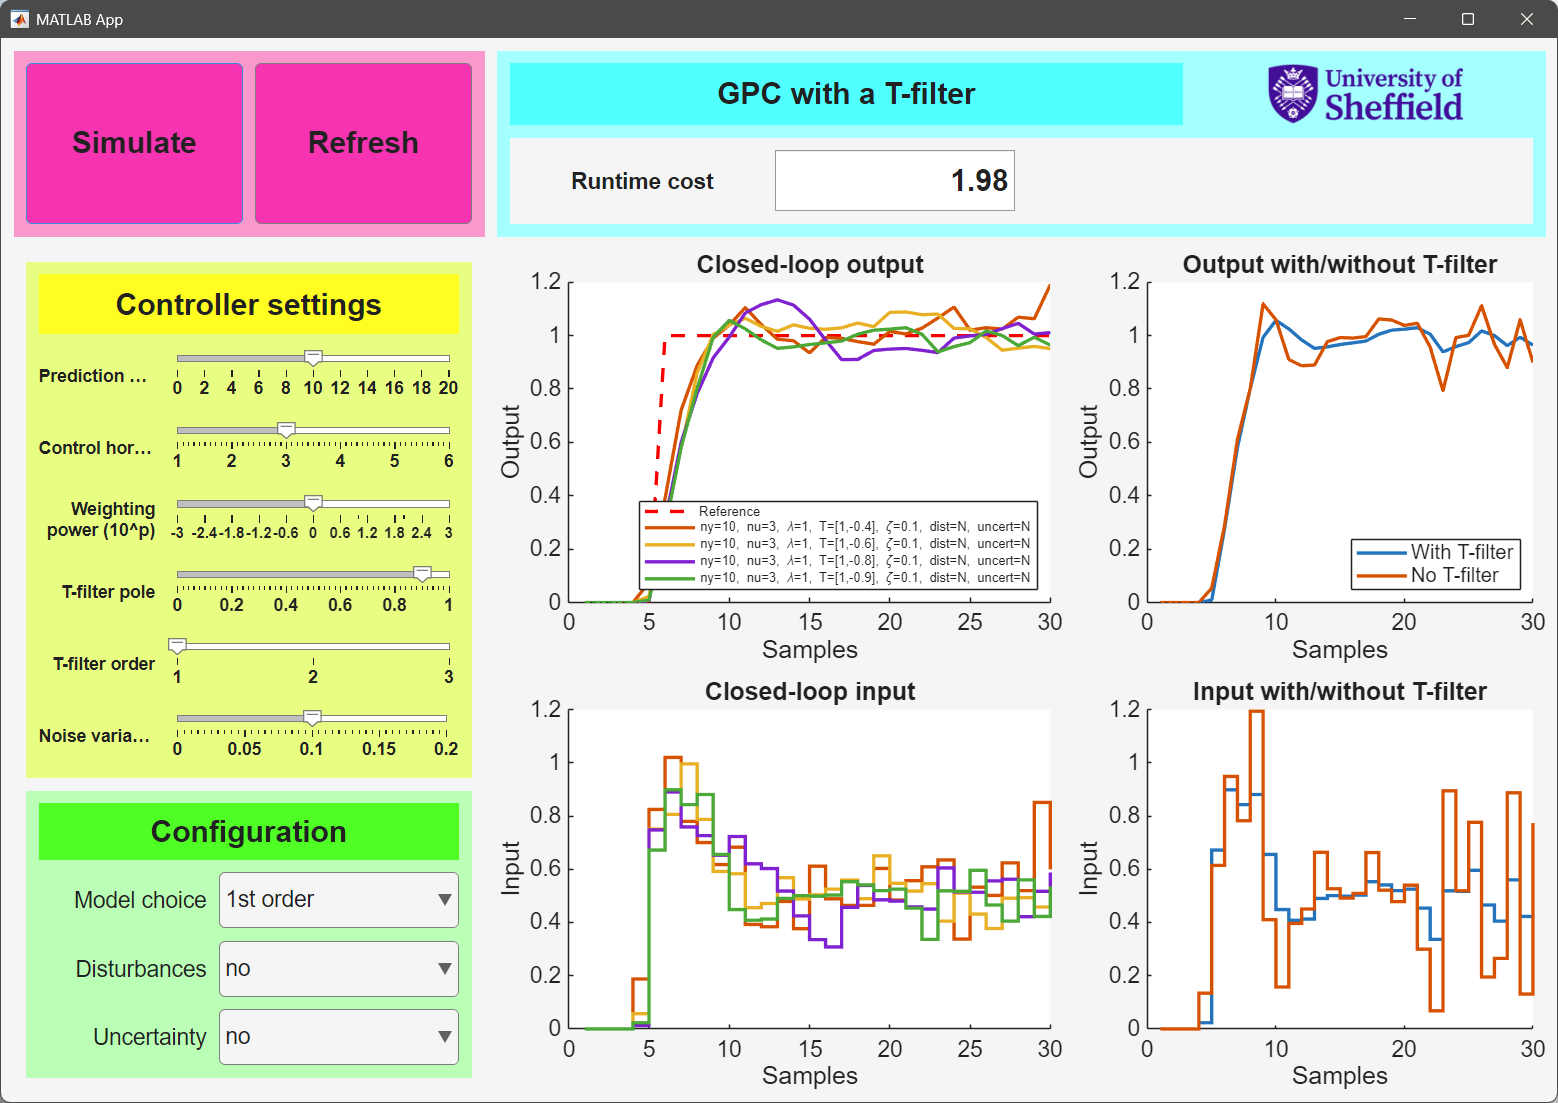

**Figure 4.1** Impact of changing the T-filter pole position (all other parameters unchanged)

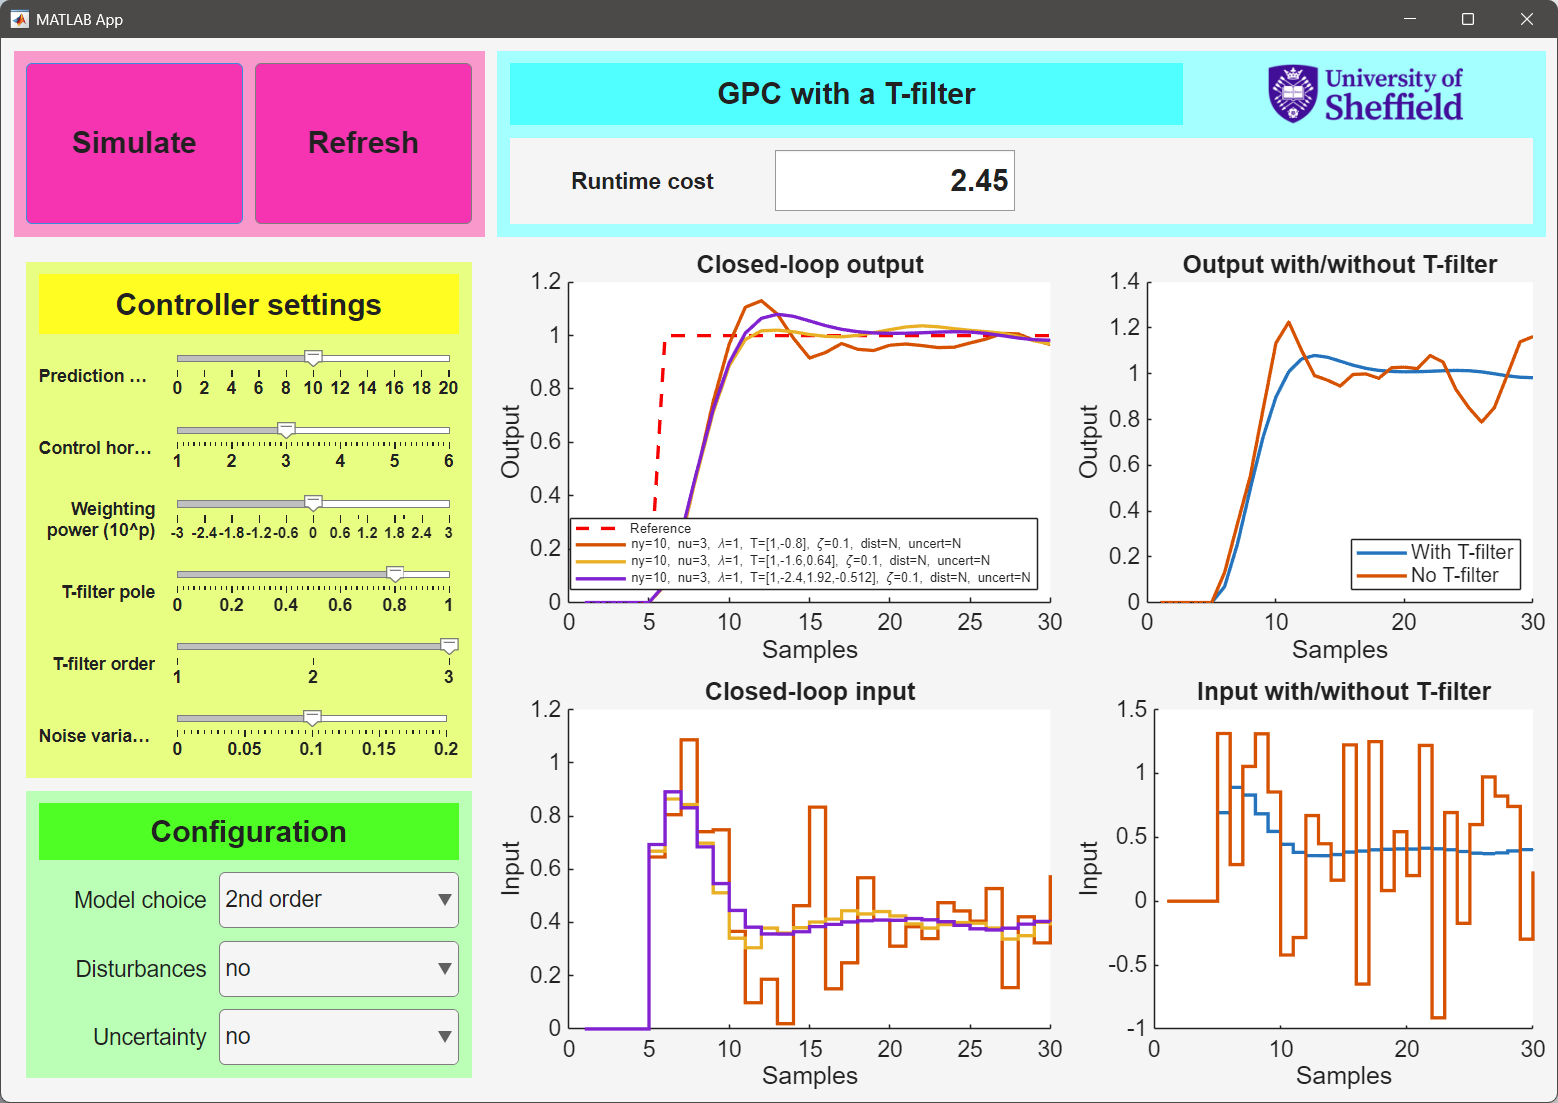

**Figure 4.2** Impact of changing the T-filter order (all other parameters unchanged)

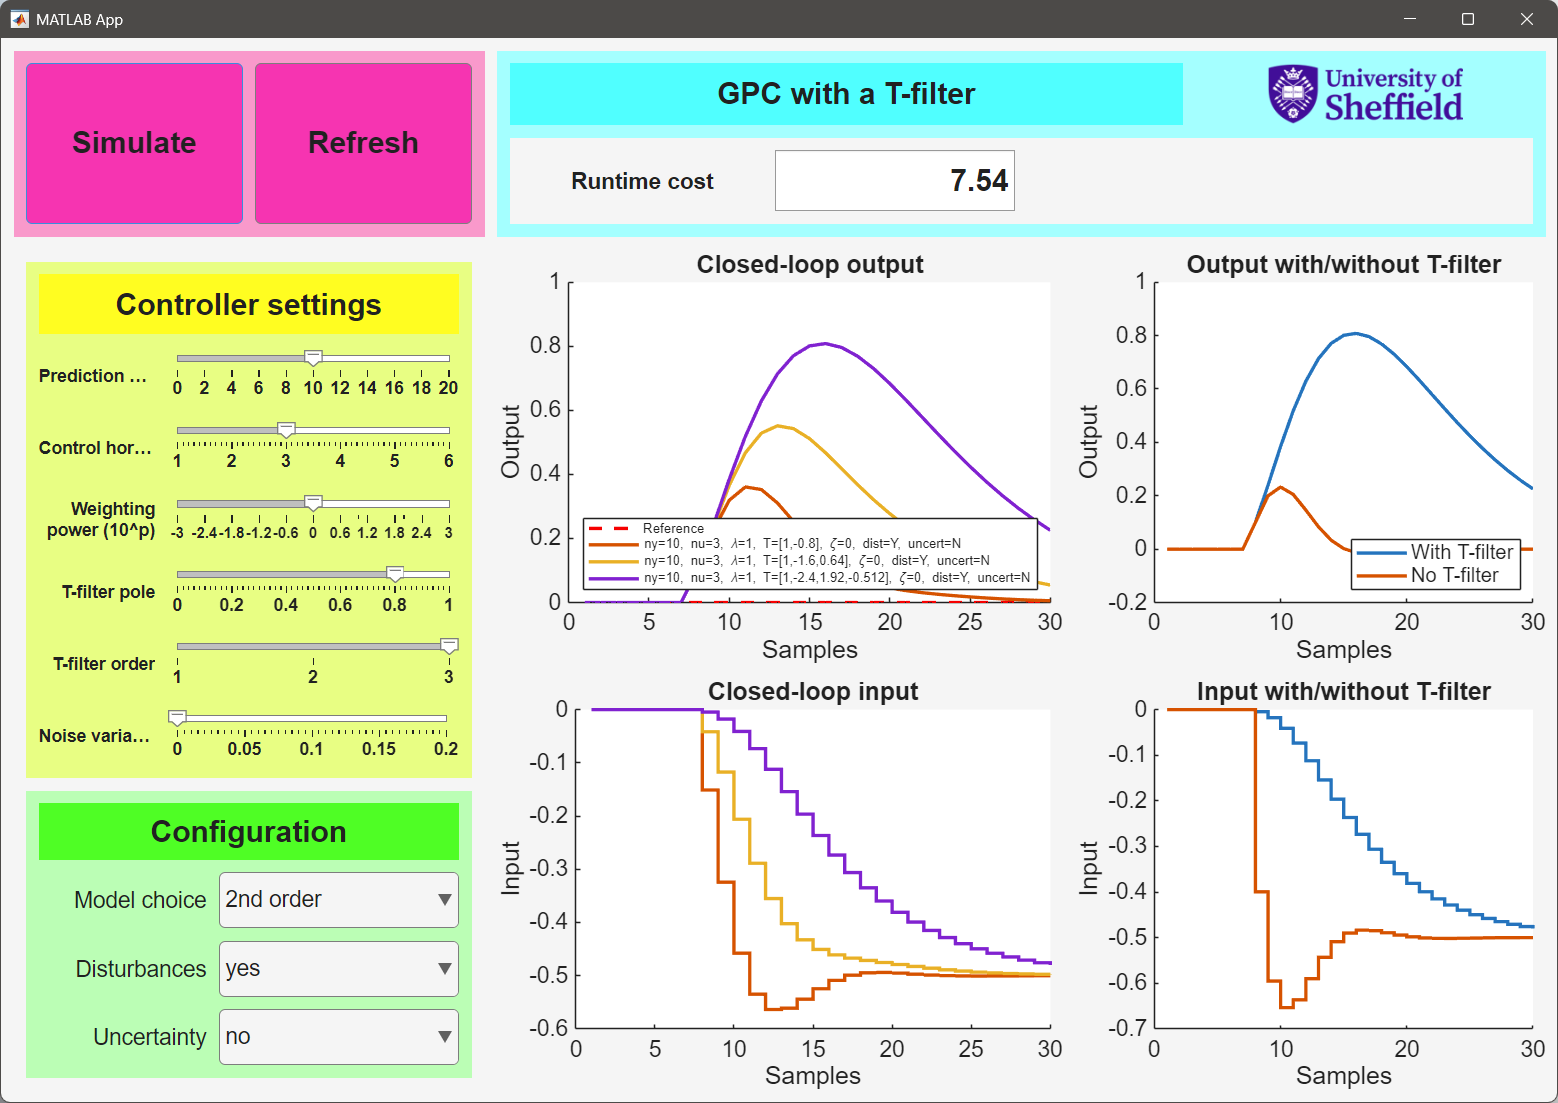

**Figure 4.3** Impact of changing the T-filter order with disturbance rejection (all other parameters unchanged)